# Tally  votes and explore the classifications and scores .

% read in table and format it to our liking.

clsTab=jellyfish.readClassification.import_classification_file_CJF('191121');
%head(clsTab,5)


## separate the Phase 1 classification table

startDate=datetime('01/06/21 00:00','InputFormat',"dd/MM/yy HH:mm");
endDate=datetime('14/06/21 23:59','InputFormat',"dd/MM/yy HH:mm");

clsTabP1=jellyfish.readClassification.format_classification_table_CJF(clsTab,'start',startDate,'end',endDate);
%head(clsTab,5)
%clsTab=jellyfish.readClassification.simulationMask(clsTab,'TNG50');

Classification info based on data downloaded on 14/7/21

review and training set objecs classifications are removed. 

The raw classification data is reformatted into a new table with columns contiaing the snapshot, id  Id for the object as well as the label (jelly or not):

%Classification data is reformatted into the following table (each line is a single classification instance):
%disp(clsTab(1:5,:))



## Separaete the phase 2 classification table


startDate=datetime('22/08/21 00:00','InputFormat',"dd/MM/yy HH:mm");
endDate=datetime('19/11/21 23:59','InputFormat',"dd/MM/yy HH:mm");

clsTabP2=jellyfish.readClassification.format_classification_table_CJF(clsTab,'start',startDate,'end',endDate);




% number of Inspectors
%Inspectors=unique(clsTab.user_name);
%Inspectors=Inspectors.replace("-","_")

% number of objects
[idListP1, ~,~]=unique(clsTabP1.subject_ids);
ngalP1=length(idListP1);

fprintf('there are %i objects in Phase I\n',ngalP1)

there are 37986 objects in Phase I




[idListP2,~,~]=unique(clsTabP2.subject_ids);
ngalP2=length(idListP2);
fprintf('there are %i objects in Phase II\n',ngalP2)

there are 51464 objects in Phase II




% create object table
objectTableP1=jellyfish.readClassification.build_object_table(clsTabP1);
objectTableP2=jellyfish.readClassification.build_object_table(clsTabP2);
objectTableP2=objectTableP2(5:end,:);  % remove first 4 objects with only 1 classification 
% table(idList,clsTab.simName(ia),clsTab.snap(ia),clsTab.subfind(ia),zeros(size(idList)),zeros(size(idList)),...
%     'variableNames',{'subject_ids','sim','snap','subfind','Ncls','Ycls'});

A table of objects is generated containing identifying information. To this we will add a classficiation column in the future:

%disp(objectTableP1(1:5,:))
snapsP1=unique(objectTableP1.snap);
zredsP1=round(10.*illustris.utils.snap2redshift(snapsP1))./10;

snapsP2=unique(objectTableP2.snap);
zredsP2=round(10.*illustris.utils.snap2redshift(snapsP2))./10;



## add classification column

% %loop over subject ids
% for i=1:length(idList)
%     inds=find(clsTab.subject_ids==idList(i));
%     
%     objectTable.Ncls(i)=length(inds); % total number of classifications 
%     
%     objectTable.Ycls(i)=sum(clsTab.isJelly(inds)); % number of 'yes' answers 
%     
%     
% end
% 
% disp(objectTable(1:5,:))



## plot scores

Here are the distributions for the total number of classifications and yes scores for the entire classification table, after removing the training annd review samples but before enforcing the dates.

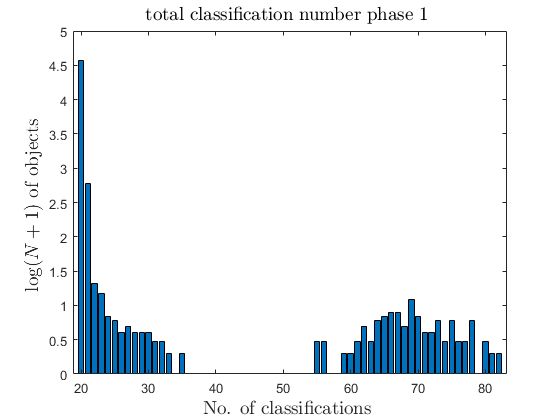

be=-0.5:1:20.5;


figure
xx=min(objectTableP1.clsNum):max(objectTableP1.clsNum);%  unique(objectTable.Ycls);
hs=histcounts(objectTableP1.clsNum,length(xx));
%histogram(objectTable.Ycls,29


 bar(xx,log10(hs+1));
% text(0:length(hs)-1,hs,num2str(hs','%0.2f'),'vert','bottom','horiz','center');
%box off
%ax=gca;
%ax.YAxis.Visible='off';

%set(gca,'ytick',[])
xlabelmine('No. of classifications ');
ylabelmine('$\log (N+1)$ of objects ');
titlemine('total classification number phase 1 ');


fprintf('percentage of objects in phase I with more than 20 classifications: %s',num2str(sum(objectTableP1.clsNum>20)./ngalP1.*100));

percentage of objects in phase I with more than 20 classifications: 1.9981

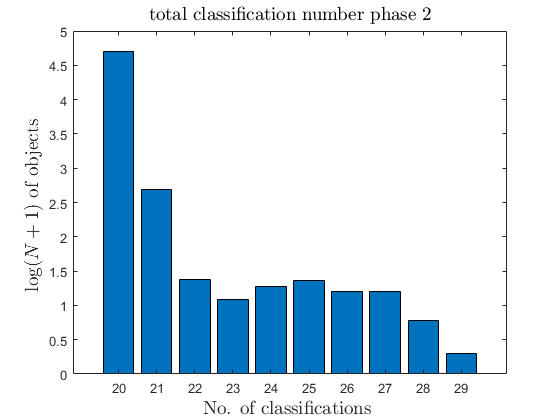




figure
xx=min(objectTableP2.clsNum):max(objectTableP2.clsNum);%  unique(objectTable.Ycls);
hs=histcounts(objectTableP2.clsNum,length(xx));
%histogram(objectTable.Ycls,29


 bar(xx,log10(hs+1));
% text(0:length(hs)-1,hs,num2str(hs','%0.2f'),'vert','bottom','horiz','center');
%box off
%ax=gca;
%ax.YAxis.Visible='off';

%set(gca,'ytick',[])
xlabelmine('No. of classifications ');
ylabelmine('$\log (N+1)$ of objects ');
titlemine('total classification number phase 2');


fprintf('percentage of objects in phase 2 with more than 20 classifications: %s',num2str(sum(objectTableP2.clsNum>20)./ngalP2.*100));

percentage of objects in phase 2 with more than 20 classifications: 1.1561

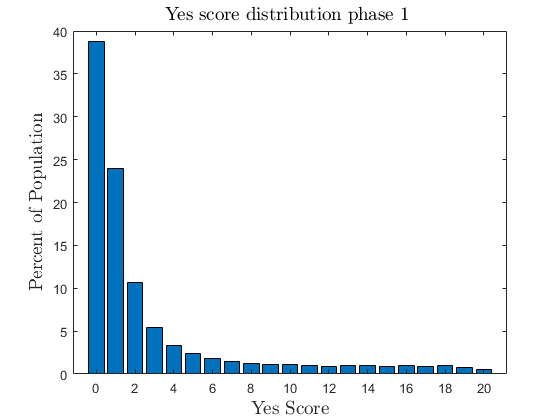





figure
hs=histcounts(objectTableP1.score,-0.5:1:20.5)/ngalP1*100;
%histogram(objectTableP1.score,29)

 bar(0:length(hs)-1,hs);
% text(0:length(hs)-1,hs,num2str(hs','%0.2f'),'vert','bottom','horiz','center');
%box off
%ax=gca;
%ax.YAxis.Visible='off';

%set(gca,'ytick',[])
xlabelmine(' Yes Score');
ylabelmine('Percent of Population');
titlemine('Yes score distribution phase 1 ');

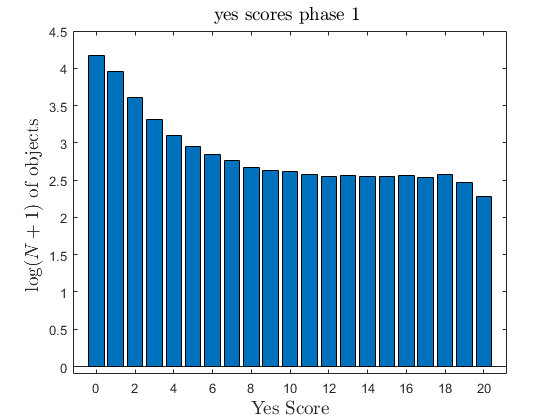



figure
hs=histcounts(objectTableP1.score,-0.5:1:20.5);%./ngal*100;
%histogram(objectTableP1.score,29)

%xx=unique(objectTableP1.score);
 bar(0:length(hs)-1,log10(hs+1));
% text(0:length(hs)-1,hs,num2str(hs','%0.2f'),'vert','bottom','horiz','center');
%box off
%ax=gca;
%ax.YAxis.Visible='off';
ylim([-0.1 4.5])
%set(gca,'ytick',[])
xlabelmine(' Yes Score');
ylabelmine('$\log (N+1)$ of objects ');
titlemine('yes scores phase 1 ');

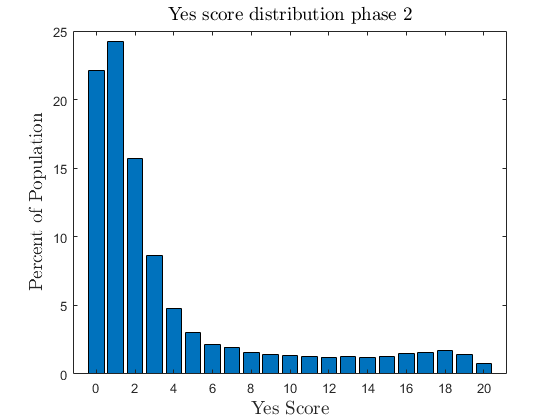




figure
hs=histcounts(objectTableP2.score,-0.5:1:20.5)/ngalP2*100;
%histogram(objectTableP2.score,29)

 bar(0:length(hs)-1,hs);
% text(0:length(hs)-1,hs,num2str(hs','%0.2f'),'vert','bottom','horiz','center');
%box off
%ax=gca;
%ax.YAxis.Visible='off';

%set(gca,'ytick',[])
xlabelmine(' Yes Score');
ylabelmine('Percent of Population');
titlemine('Yes score distribution phase 2');

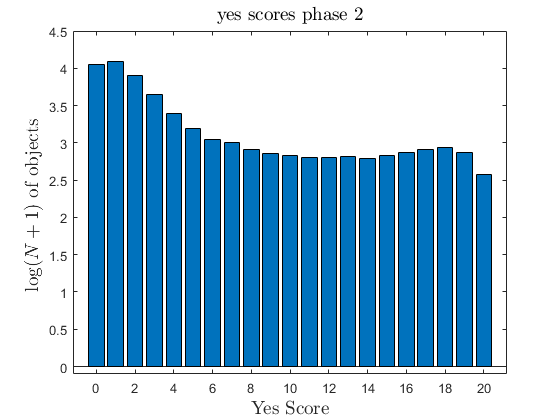



figure
hs=histcounts(objectTableP2.score,-0.5:1:20.5);%./ngal*100;
%histogram(objectTableP2.score,29)

%xx=unique(objectTableP2.score);
 bar(0:length(hs)-1,log10(hs+1));
% text(0:length(hs)-1,hs,num2str(hs','%0.2f'),'vert','bottom','horiz','center');
%box off
%ax=gca;
%ax.YAxis.Visible='off';
ylim([-0.1 4.5])
%set(gca,'ytick',[])
xlabelmine(' Yes Score');
ylabelmine('$\log (N+1)$ of objects ');
titlemine('yes scores phase 2');

## identify double objects in the two phases

doubleIndP1=[];
doubleIndP2=[];

cnt=0;
for i=1:height(objectTableP1)
    
%     if mod(i,1000)==0
%         fprintf('%i ',i/1000);
%     end
    
    msk=strcmp(objectTableP1.sim(i),objectTableP2.sim) & objectTableP2.snap==objectTableP1.snap(i);
    ii=find(msk & objectTableP2.subfind==objectTableP1.subfind(i));
    
    if ~isempty(ii)
        cnt=cnt+1;
        doubleIndP1(cnt)=i;  % index of object in table 
        doubleIndP2(cnt)=ii; % index of object in table 
        
    end
    
end

dp1=objectTableP1.score(doubleIndP1);
dp2=objectTableP2.score(doubleIndP2);


 fprintf('found %i doubles between phase I and phase II \n',cnt)

found 8006 doubles between phase I and phase II 


fprintf('No. of pbjects with higher scores in phaseII: %i , %3.1f %% \n',...
    sum(dp2>dp1),sum(dp2>dp1)/cnt*100)

No. of pbjects with higher scores in phaseII: 4391 , 54.8 % 


fprintf('No. of pbjects with lower scores in phaseII: %i , %3.1f %%\n',...
    sum(dp2<dp1),sum(dp2<dp1)/cnt*100)

No. of pbjects with lower scores in phaseII: 1766 , 22.1 %


fprintf('No. of pbjects with equal scores in phaseII: %i , %3.1f %%\n',...
    sum(dp2==dp1),sum(dp2==dp1)/cnt*100)

No. of pbjects with equal scores in phaseII: 1849 , 23.1 %


fprintf('No. of objects which are JF in II: %i , %3.1f %%\n',...
    sum(dp2>=16),sum(dp2>=16 )/cnt*100)

No. of objects which are JF in II: 565 , 7.1 %


fprintf('No. of objects which are JF in I : %i , %3.1f %%\n',...
    sum(dp1>=16),sum( dp1>=16)/cnt*100)

No. of objects which are JF in I : 413 , 5.2 %


fprintf('increase is  : %3.1f %%\n',...
    (sum(dp2>=16)./sum(dp1>=16)-1).*100)

increase is  : 36.8 %


fprintf('No. of objects which are JF in II but not in I: %i , %3.1f %%\n',...
    sum(dp2>=16 & dp1<16),sum(dp2>=16 & dp1<16)/cnt*100)

No. of objects which are JF in II but not in I: 256 , 3.2 %


fprintf('No. of objects which are JF in I but not in II: %i , %3.1f %%\n',...
    sum(dp2<16 & dp1>=16),sum(dp2<16 & dp1>=16)/cnt*100)

No. of objects which are JF in I but not in II: 104 , 1.3 %


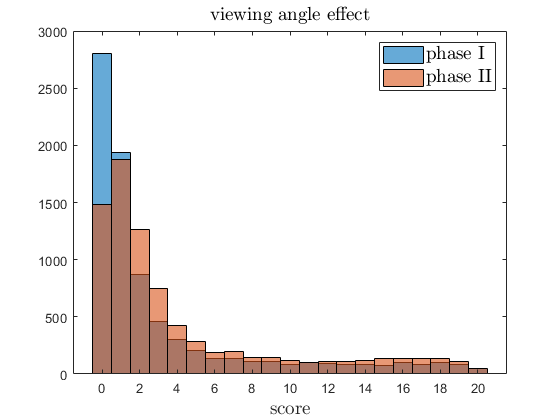

h=[];
figure
h(end+1)=histogram(dp1,be,...
    'DisplayName','phase I');
hold on 
h(end+1)=histogram(dp2,be,...
    'DisplayName','phase II');
legend(h,'Interpreter','latex','fontsize',14)
xlabelmine('score');
titlemine('viewing angle effect');

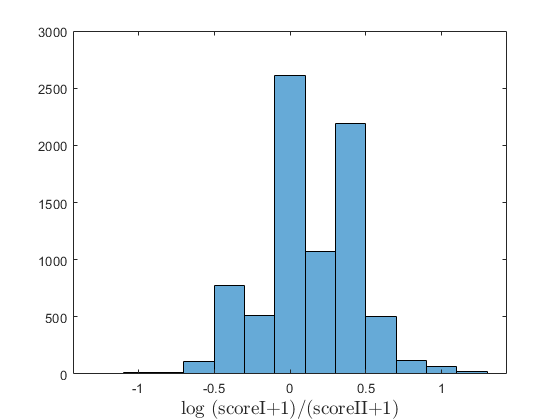



figure
histogram(log10((dp2+1)./(dp1+1)),-1.3:0.2:1.3)
%plot(objectTableP1.score(doubleP1),,'x');
%hold on 
%plot([0 20],[0 20],':k')
xlabelmine('log (scoreI+1)/(scoreII+1)');

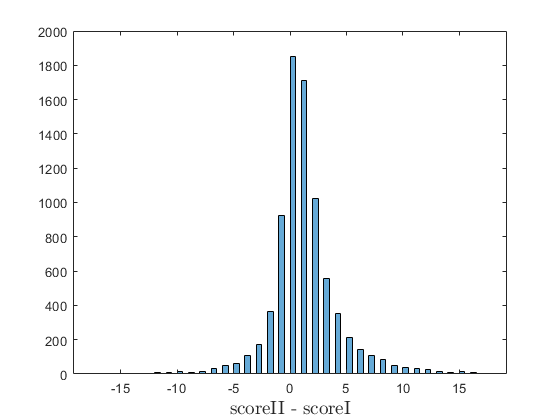

%ylabelmine('phase II score');

figure
histogram(dp2-dp1,-17.5:0.5:17.5)
%plot(objectTableP1.score(doubleP1),,'x');
%hold on 
%plot([0 20],[0 20],':k')
xlabelmine('scoreII - scoreI');

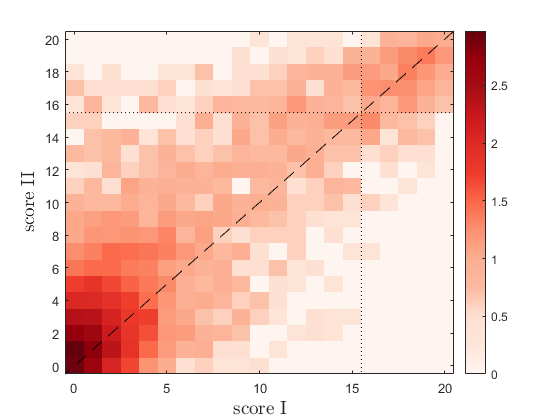



[bird, binsize, xl,yl]= histogram2d(dp1,dp2,ones(size(dp1)),'len',21);
figure
imagesc(xl,yl,log10(squeeze(bird(:,:,1))))
hold on
plot([-0.5 21],[-0.5 21],'--k')
plot([15.5 15.5],[-0.5 21],':k')
plot([-0.5 21],[15.5 15.5],':k')
xlabelmine('score I');
ylabelmine('score II');
colormap(brewermap(256,'Reds'))
set(gca,'ydir','normal')
colorbar

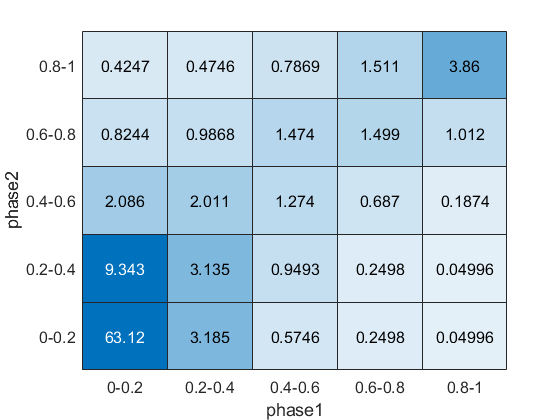


figure
edj=0:0.2:1;
edj(end)=1.01;
len=length(edj)-1;
cdata=zeros(len,len);
for i=1:len
    for j=1:len
        cdata(i,j)=sum((dp2./20>=edj(i) & dp2./20<edj(i+1)) & ...
            (dp1./20>=edj(j) & dp1./20<edj(j+1)) );
    end
end
 
 cdata=cdata./cnt.*100;
 lab={'0-0.2' '0.2-0.4' '0.4-0.6' '0.6-0.8' '0.8-1'};
% imagesc(cdata)
% caxis([0 10])
% set(gca,'Ydir','normal','xtick',1:5,'xticklabel',lab,...
%     'ytick',1:5,'yticklabel',lab)
% colormap(cmap)

figure
ht=heatmap(lab,fliplr(lab),flipud(cdata));
caxis([0 7 ])
colorbar('off')
ht.xlabel('phase1')
ht.ylabel('phase2')
ht.FontSize=12;

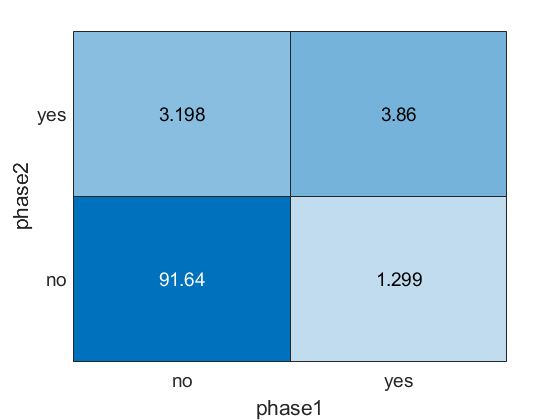



jfThresh=0.8;
jfCJF=dp2/20>=jfThresh;
jf50=dp1/20>=jfThresh;



jfdata=[sum(jfCJF & ~jf50) , sum(jfCJF & jf50);...
    sum(~jfCJF & ~jf50) , sum(~jfCJF & jf50)]./cnt*100;
ht=heatmap(["no " "yes "],["yes " "no "],jfdata);
ht.FontSize=14;
caxis([0 8])
colorbar('off')
ht.xlabel('phase1')
ht.ylabel('phase2')

fprintf("total agreement on what is or isn't JF (score>=%s)= %s %% \n",...
   num2str(jfThresh), num2str(jfdata(1,2)+jfdata(2,1)))

total agreement on what is or isn't JF (score>=0.8)= 95.5034 % 
